clear all; close all;
addpath ./embedded
addpath ./mifiltertools
addpath ./utils
format LONGE

Fm=2;

Fc=1.2;
Fs=1.5;
Ap=0.5;
As=15;

[N,e]=mi_cheb1ord(Fc, Fs, Ap, As)

N =      4


e =      3.493114001889480e-01


[BS,AS]=mi_cheby1(N,e);

%[Bs,As]=mi_lp2lp(BS,AS,2*pi*1000);


[Bz,Az]=bilinear(BS,AS,Fm/2);
Az=Az/(Bz(1))

Az =   124.2857 -298.5000  332.8765 -187.7854   45.1232


Bz=Bz/(Bz(1))

Bz =     1.0000    4.0000    6.0000    4.0000    1.0000



[Bz1,Az1]=mi_bilinear(BS,AS,Fm);

Az1=Az1/(Bz1(1))

Az1 =     1.3581   -4.4644    5.7620   -3.4359    0.7963


Bz1=Bz1/(Bz1(1))

Bz1 =     1.0000    3.9999    5.7620    3.9999    1.0000


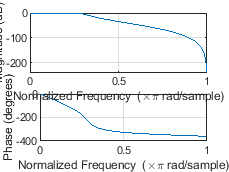


freqz(Bz,Az)

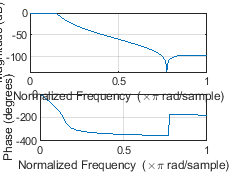

freqz(Bz1,Az1)

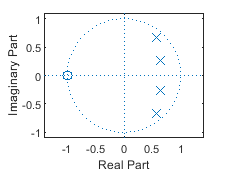

figure;zplane(Bz,Az);

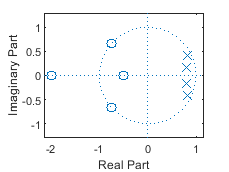

figure;zplane(Bz1,Az1);